% format long;
% addpath(genpath('../../20231127计算结果'))
% clear;
% k = 0.005:0.005:50;
% loadflag = 0; % 载入标志 1 重新装载数据，读取色散关系。适用于第一次运行程序。在第一次运行过后可将此变量置为0
%               % 以避免重复运行时多次加载大尺寸数据
% if loadflag
%     filename(10) = "";
%     F12 = [];
%     for i = 1:10
%         filename(i) = append("F12_", num2str(1000*i-999), "_", num2str(1000*i), ".mat");
%         load(filename(i));
%         F12 = [F12;each_group_F12];
%     end
%     w_index = find_sign_change(F12);
%     w = w_index * 0.00001;
% end

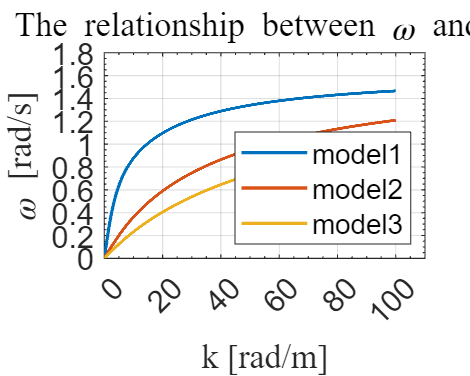

load dispersion_relation.mat
figure(1)
i = 1:20000;
mean_w = (w(mod(i,5)==1,:) + w(mod(i,5)==2,:) + w(mod(i,5)==3,:) + w(mod(i,5)==4,:) + w(mod(i,5)==0,:))/5;
k = (1:4000)*0.025;
p = plot(k, mean_w(:, 1:3));
p(3).LineWidth = 1.5;
% p(3).Marker = 'square';
p(3).MarkerSize = 10;
p(3).LineStyle = '-';
p(2).LineWidth = 1.5;
% p(2).Marker = 'diamond';
p(2).MarkerSize = 10;
p(2).LineStyle = '-';
p(1).LineWidth = 1.5;
% p(1).Marker = 'pentagram';
p(1).MarkerSize = 10;
p(1).LineStyle = '-';
xlabel('k [rad/m]', 'FontSize', 14, 'FontName', 'Times New Roman');
xlim([0, 110])
xticks(0:20:120) % 设置 X 轴的大刻度分度值，范围是 0 到 110，步长为 10
ylim([0, 1.8])
yticks(0:0.2:1.8) % 设置 Y 轴的大刻度分度值，范围是 0 到 1.8，步长为 0.2
ylabel('\omega [rad/s]', 'FontSize', 14, 'FontName', 'Times New Roman');
title('The relationship between \omega and k', 'FontSize', 14, 'FontName', 'Times New Roman');
legend('model1', 'model2', 'model3', 'Location', 'southeast');
grid on;
set(gca, 'FontSize', 14, 'XMinorTick', 'on', 'YMinorTick', 'on');
set(gcf, 'Position', [100, 100, 500, 400]);

                                                                                        
$$\textbf{相速度：}c_p = \frac{\omega(k)}{k} \\
\textbf{群速度：}c_g = \frac{d\omega(k)}{dk}$$


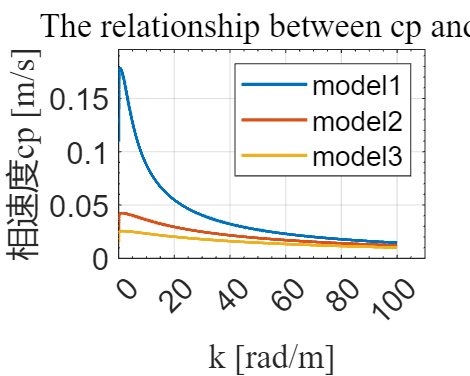

% 计算群速度和相速度
cp = mean_w./k';
cg = diff(mean_w)/0.025;

figure(2)
p = plot(k, cp(:, 1:3));
p(3).LineWidth = 1.5;
% p(3).Marker = 'square';
p(3).MarkerSize = 10;
p(3).LineStyle = '-';
p(2).LineWidth = 1.5;
% p(2).Marker = 'diamond';
p(2).MarkerSize = 10;
p(2).LineStyle = '-';
p(1).LineWidth = 1.5;
% p(1).Marker = 'pentagram';
p(1).MarkerSize = 10;
p(1).LineStyle = '-';
xlabel('k [rad/m]', 'FontSize', 14, 'FontName', 'Times New Roman');
xlim([0, 110])
xticks(0:20:120) % 设置 X 轴的大刻度分度值，范围是 0 到 110，步长为 10
ylim([0, 1.1*max(cp(:))])
% yticks(0:0.2:1.8) % 设置 Y 轴的大刻度分度值，范围是 0 到 1.8，步长为 0.2
ylabel('相速度cp [m/s]', 'FontSize', 14, 'FontName', 'Times New Roman');
title('The relationship between cp and k', 'FontSize', 14, 'FontName', 'Times New Roman');
legend('model1', 'model2', 'model3', 'Location', 'northeast');
grid on;
set(gca, 'FontSize', 14, 'XMinorTick', 'on', 'YMinorTick', 'on');

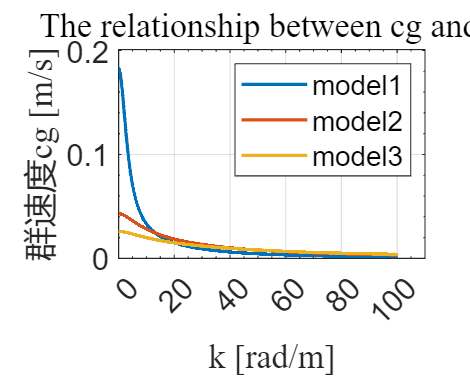

set(gcf, 'Position', [100, 100, 500, 400]);

figure(3)
p = plot(k(1:end-1), cg(:, 1:3));
p(3).LineWidth = 1.5;
% p(3).Marker = 'square';
p(3).MarkerSize = 10;
p(3).LineStyle = '-';
p(2).LineWidth = 1.5;
% p(2).Marker = 'diamond';
p(2).MarkerSize = 10;
p(2).LineStyle = '-';
p(1).LineWidth = 1.5;
% p(1).Marker = 'pentagram';
p(1).MarkerSize = 10;
p(1).LineStyle = '-';
xlabel('k [rad/m]', 'FontSize', 14, 'FontName', 'Times New Roman');
xlim([0, 110])
xticks(0:20:120) % 设置 X 轴的大刻度分度值，范围是 0 到 110，步长为 10
ylim([0, 1.1*max(cg(:))])
% yticks(0:0.2:1.8) % 设置 Y 轴的大刻度分度值，范围是 0 到 1.8，步长为 0.2
ylabel('群速度cg [m/s]', 'FontSize', 14, 'FontName', 'Times New Roman');
title('The relationship between cg and k', 'FontSize', 14, 'FontName', 'Times New Roman');
legend('model1', 'model2', 'model3', 'Location', 'northeast');
grid on;
set(gca, 'FontSize', 14, 'XMinorTick', 'on', 'YMinorTick', 'on');

set(gcf, 'Position', [100, 100, 500, 400]);